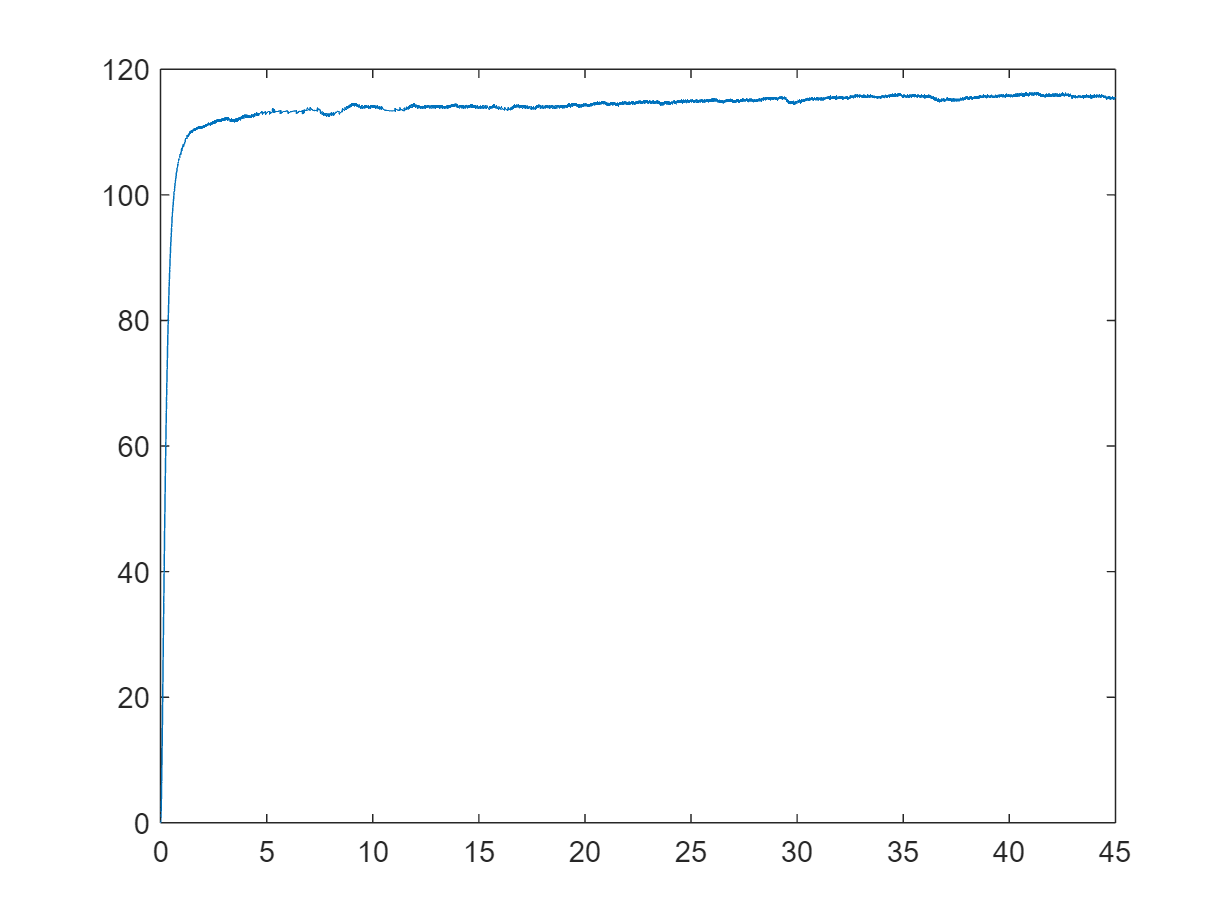

data_50.time = motor_speed.time;
data_50.speed = squeeze(motor_speed.signals.values);
% Plot speed vs. time
plot(data_50.time, data_50.speed);

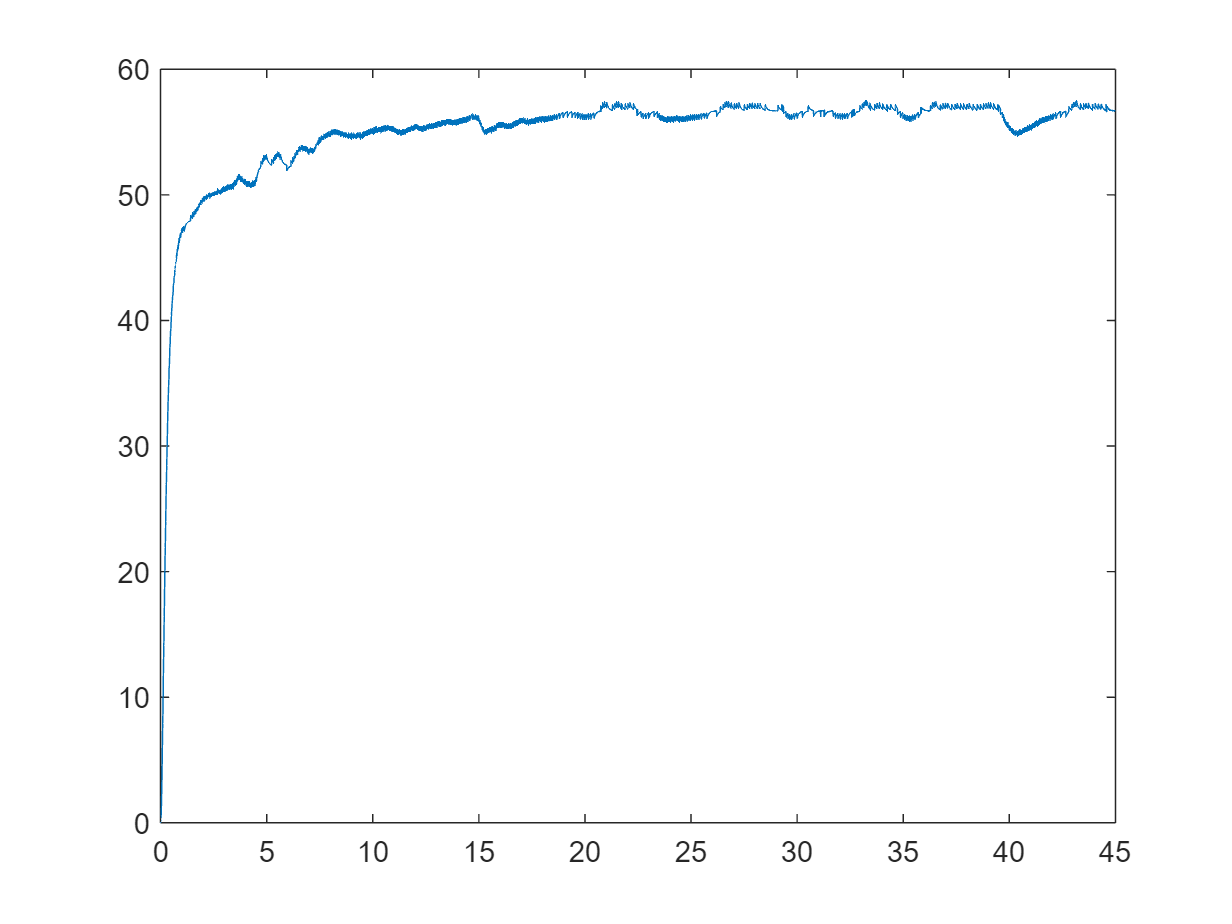

data_30.speed = squeeze(motor_speed_30.signals.values);
% Plot speed vs. time
plot(data_50.time, data_30.speed);

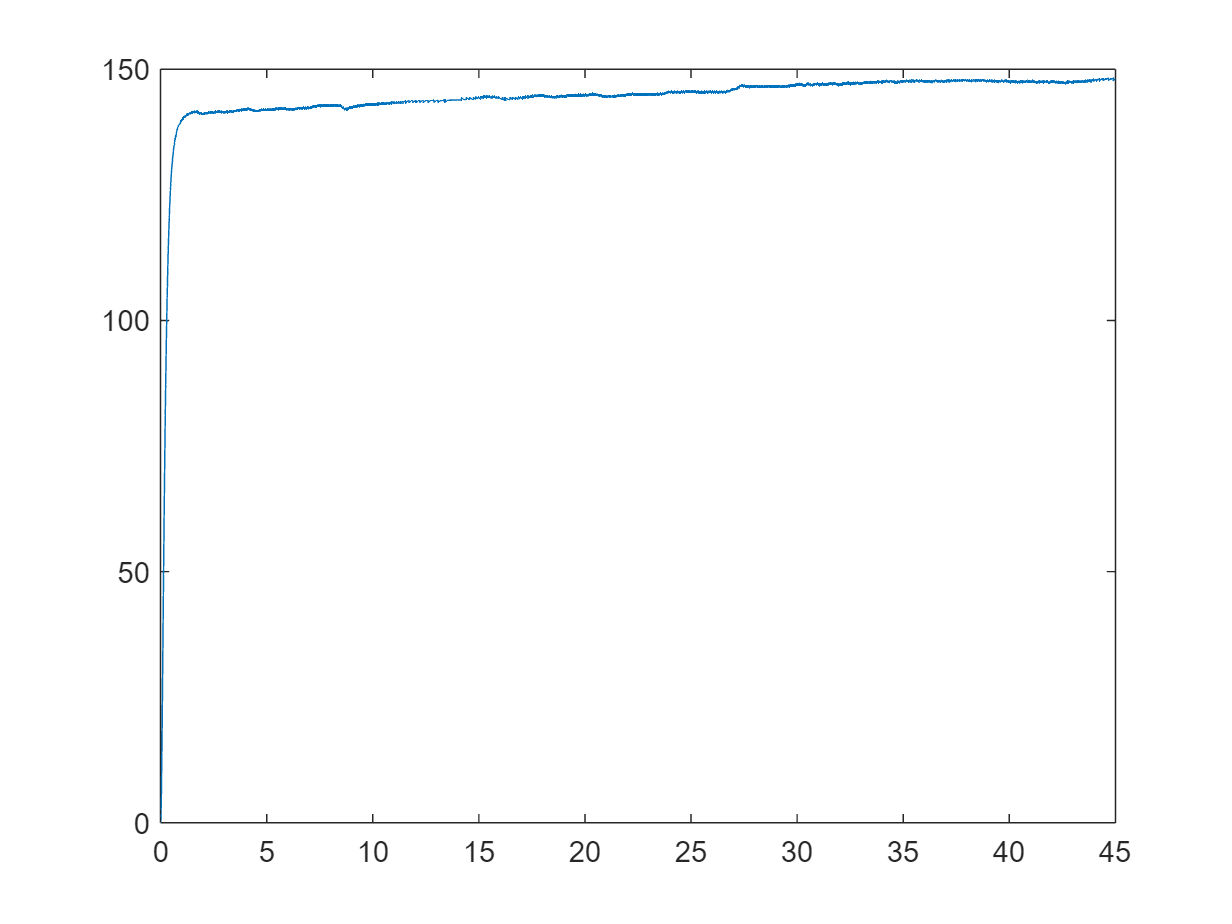

data_70.speed = squeeze(motor_speed_70.signals.values);
% Plot speed vs. time
plot(data_50.time, data_70.speed);

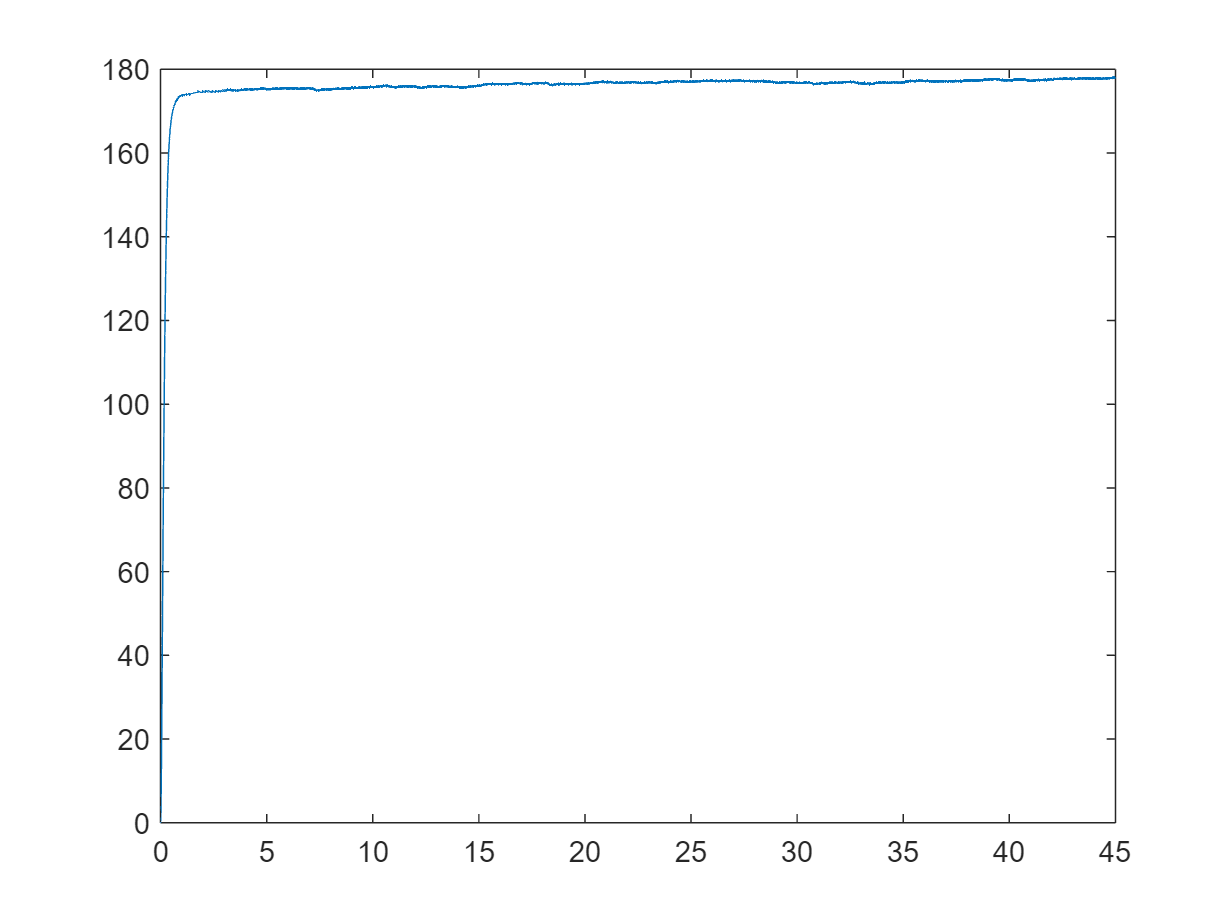

data_100.speed = squeeze(motor_speed_100.signals.values);
% Plot speed vs. time
plot(data_50.time, data_100.speed);

# Analyze the Data to Find the Time constant and the Gain for Transfer Function

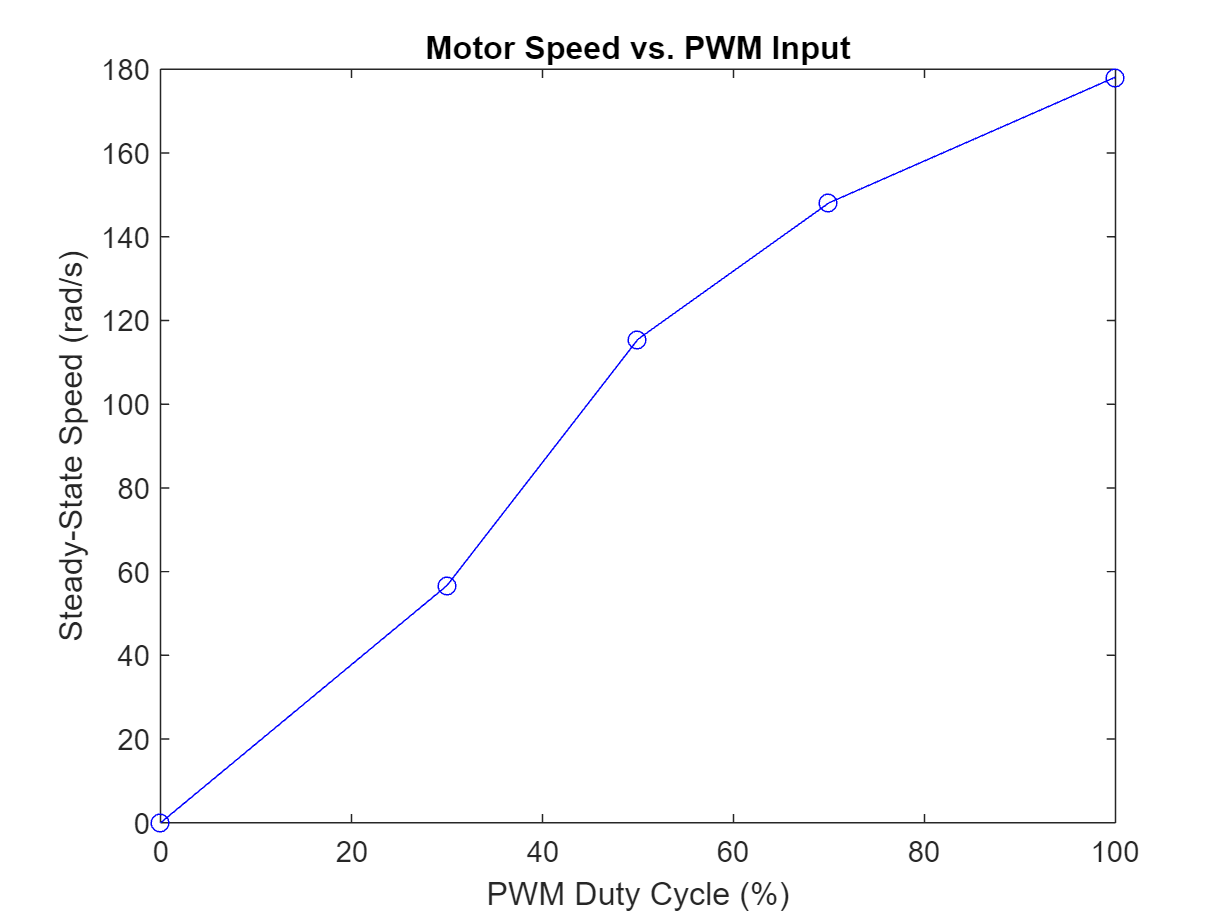

ss_speed_30 = data_30.speed(end);
ss_speed_50 = data_50.speed(end);
ss_speed_70 = data_70.speed(end);
ss_speed_100 = data_100.speed(end);

pwm_values = [0, 30, 50, 70, 100];
ss_speeds = [0, ss_speed_30, ss_speed_50, ss_speed_70, ss_speed_100];

plot(pwm_values, ss_speeds, 'bo-');
xlabel('PWM Duty Cycle (%)');
ylabel('Steady-State Speed (rad/s)');
title('Motor Speed vs. PWM Input');


polyfit(pwm_values, ss_speeds, 1)

ans =     1.8508    7.1498


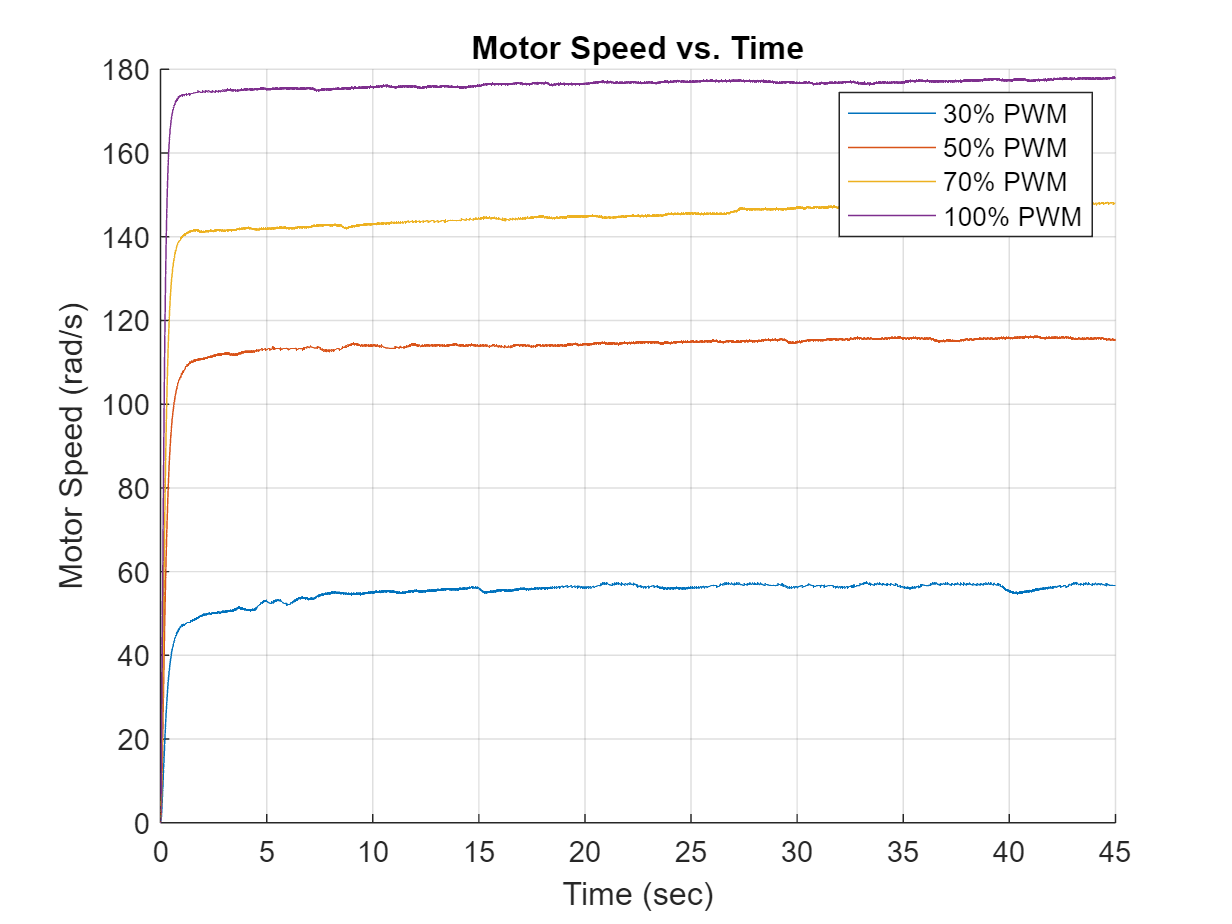

figure;
hold on;
% Plot 1: 30% PWM
% Use squeeze() to fix the [1x1xN] data dimension error
plot(data_50.time, data_30.speed);

% Plot 2: 50% PWM
plot(data_50.time, data_50.speed);

% Plot 3: 70% PWM
plot(data_50.time, data_70.speed);

% Plot 4: 100% PWM
plot(data_50.time, data_100.speed);

% We are finished adding plots to the figure
hold off;
xlabel('Time (sec)');
ylabel('Motor Speed (rad/s)');
title('Motor Speed vs. Time');
legend('30% PWM', '50% PWM', '70% PWM', '100% PWM');
grid on;

speed_63_percent_50PWM = 0.632 * ss_speed_50

speed_63_percent_50PWM = 73.0133

speed_63_percent_30PWM = 0.632 * ss_speed_30

speed_63_percent_30PWM = 35.8277

speed_63_percent_70PWM = 0.632 * ss_speed_70

speed_63_percent_70PWM = 93.5965

speed_63_percent_100PWM = 0.632 * ss_speed_100

speed_63_percent_100PWM = 112.5750

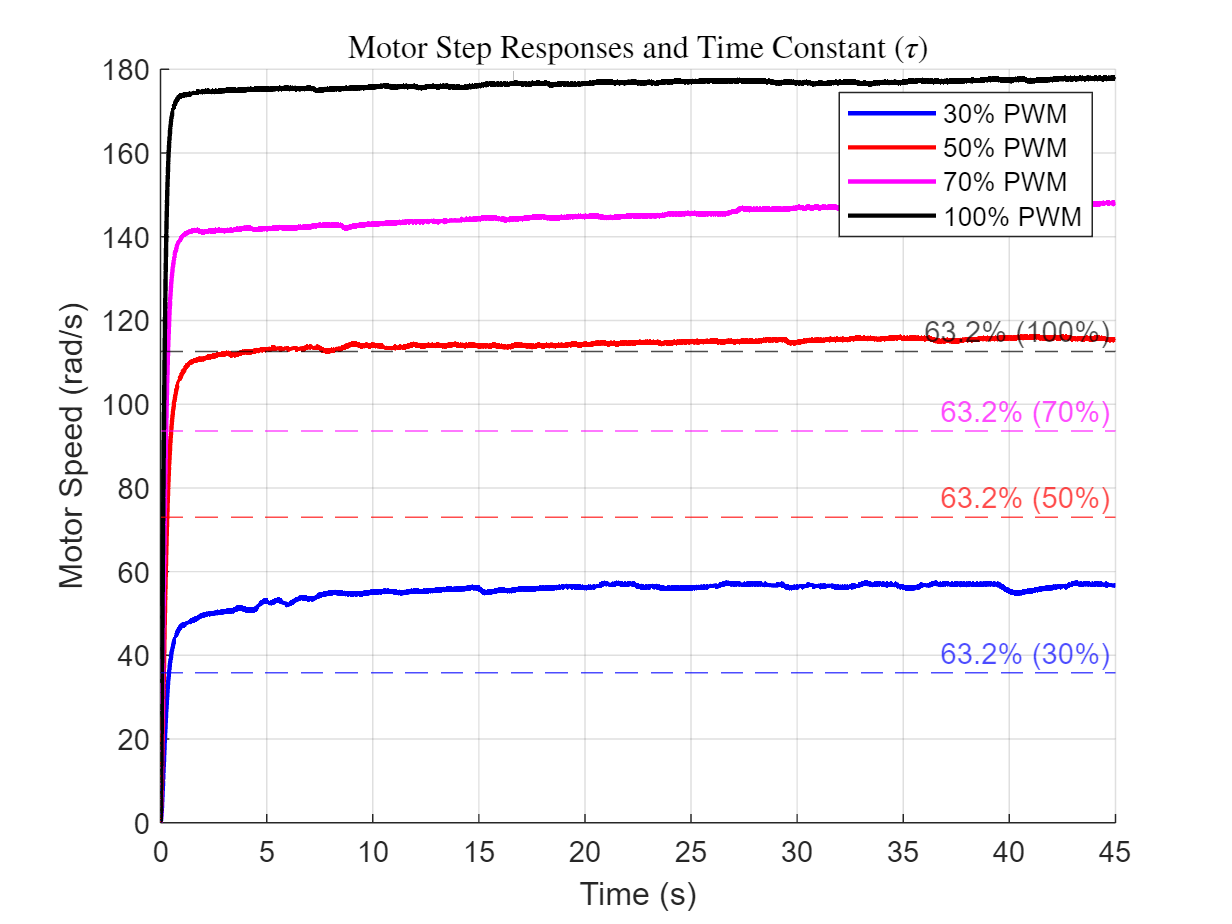

% --- 1. Your 63.2% Speed Values ---
% These are the target values you calculated
speed_63_30 = 35.8277;
speed_63_50 = 73.0133;
speed_63_70 = 93.5965;
speed_63_100 = 112.5750;



% --- 3. Plot Speed Trajectories ---
figure;
hold on;
plot(data_50.time, data_30.speed, 'b-', 'LineWidth', 1.5);
plot(data_50.time, data_50.speed, 'r-', 'LineWidth', 1.5);
plot(data_50.time, data_70.speed, 'm-', 'LineWidth', 1.5);
plot(data_50.time, data_100.speed, 'k-', 'LineWidth', 1.5);

% --- 4. Plot the 63.2% Horizontal Lines ---
% yline() is an easy way to draw a horizontal line
yline(speed_63_30, 'b--', '63.2% (30%)');
yline(speed_63_50, 'r--', '63.2% (50%)');
yline(speed_63_70, 'm--', '63.2% (70%)');
yline(speed_63_100, 'k--', '63.2% (100%)');

% --- 5. Find the Time Constant (tau) for Each Run ---
% We find the *first index* where the speed is >= the 63.2% target
idx_30 = find(data_30.speed >= speed_63_30, 1, 'first');
tau_30 = data_50.time(idx_30);

idx_50 = find(data_50.speed >= speed_63_50, 1, 'first');
tau_50 = data_50.time(idx_50);

idx_70 = find(data_70.speed >= speed_63_70, 1, 'first');
tau_70 = data_50.time(idx_70);

idx_100 = find(data_100.speed >= speed_63_100, 1, 'first');
tau_100 = data_50.time(idx_100);

% --- 6. Calculate Average Tau ---
tau_avg = (tau_30 + tau_50 + tau_70 + tau_100) / 4;

% --- 7. Finalize Plot and Display Results ---
hold off;
title('Motor Step Responses and Time Constant ($\tau$)', 'Interpreter', 'latex');
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)'); % Adjust units if needed
legend('30% PWM', '50% PWM', '70% PWM', '100% PWM');
grid on;

fprintf('Tau for 30%% PWM (at %.2f): %.4f s\n', speed_63_30, tau_30);

Tau for 30% PWM (at 35.83): 0.4000 s


fprintf('Tau for 50%% PWM (at %.2f): %.4f s\n', speed_63_50, tau_50);

Tau for 50% PWM (at 73.01): 0.3200 s


fprintf('Tau for 70%% PWM (at %.2f): %.4f s\n', speed_63_70, tau_70);

Tau for 70% PWM (at 93.60): 0.2700 s


fprintf('Tau for 100%% PWM (at %.2f): %.4f s\n', speed_63_100, tau_100);

Tau for 100% PWM (at 112.58): 0.2000 s


fprintf('Average Time Constant (τ): %.4f s\n', tau_avg);

Average Time Constant (τ): 0.2975 s
